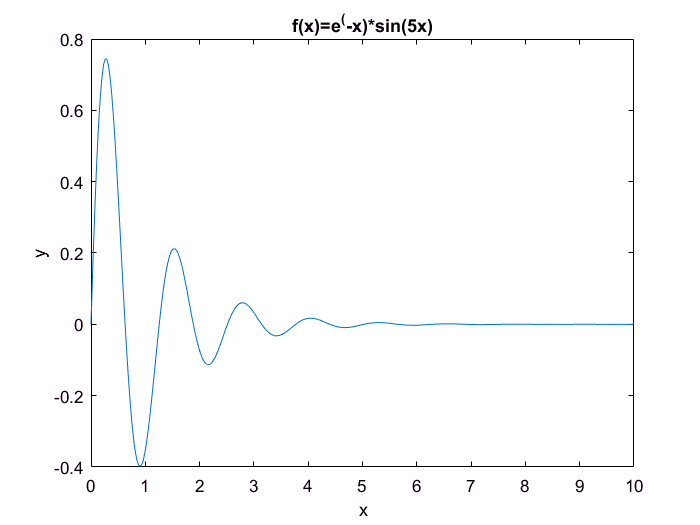

%%
clear;                   %clearing all variables
x=0:.01:10;              %initilizing x and then introducing the functions.
f=exp(-x).*sin(5*x);
g=exp(x).*sin(5*x);
t=0:.01:5;

h=sin(pi*t)./(pi*t);
l=sin(t.^2);
%opening a new figure for each function with command "figure"
%and adding title and labels.
figure(1);plot(x,f);title('f(x)=e^(-x)*sin(5x)');xlabel('x');ylabel('y');    

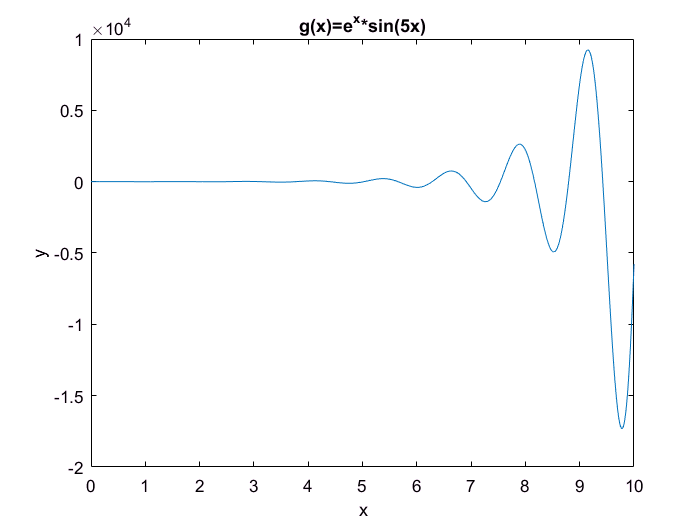

figure(2);plot(x,g);title('g(x)=e^x*sin(5x)');xlabel('x');ylabel('y');

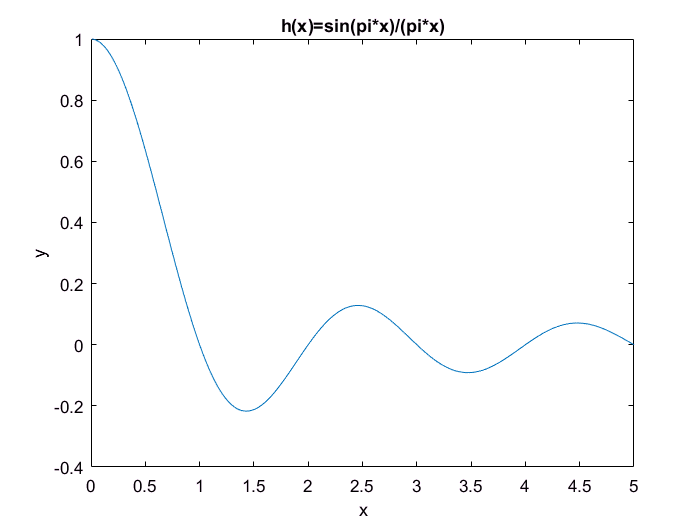

figure(3);plot(t,h);title('h(x)=sin(pi*x)/(pi*x)');xlabel('x');ylabel('y');

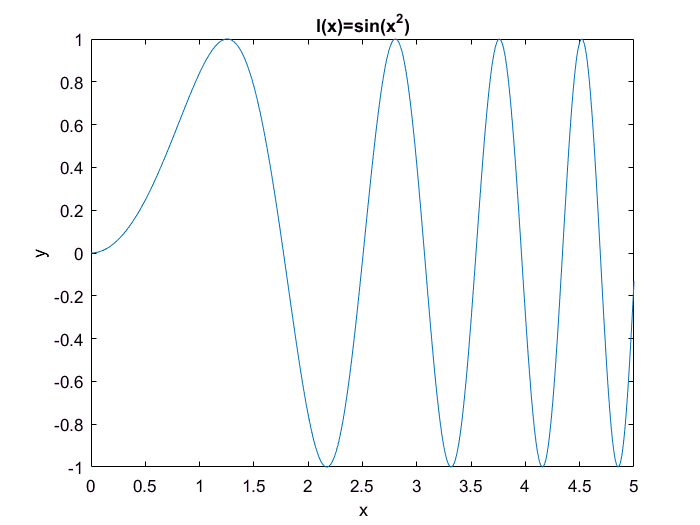

figure(4);plot(t,l);title('l(x)=sin(x^2)');xlabel('x');ylabel('y');

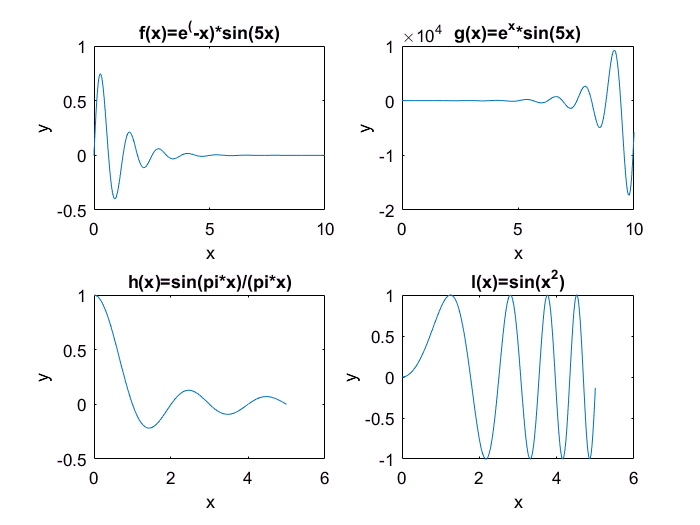



%%
%ploting all 4 functions in a single figure.
figure(5);
subplot(2,2,1);plot(x,f);title('f(x)=e^(-x)*sin(5x)');xlabel('x');ylabel('y');
subplot(2,2,2);plot(x,g);title('g(x)=e^x*sin(5x)');xlabel('x');ylabel('y');
subplot(2,2,3);plot(t,h);title('h(x)=sin(pi*x)/(pi*x)');xlabel('x');ylabel('y');
subplot(2,2,4);plot(t,l);title('l(x)=sin(x^2)');xlabel('x');ylabel('y');

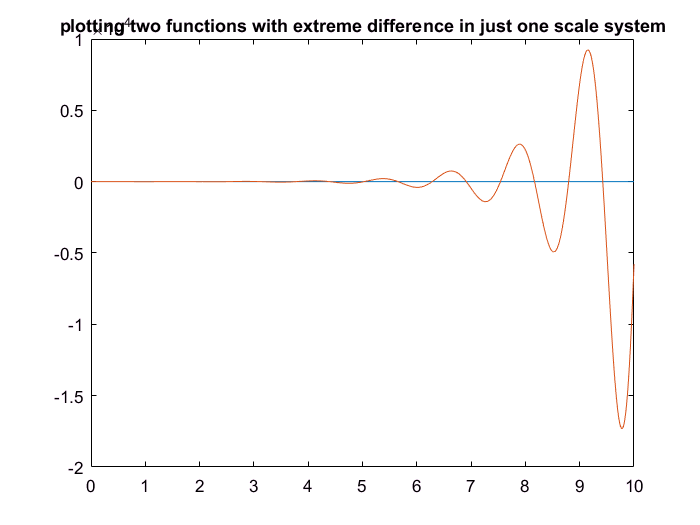

%%
figure;
%ploting functions f and g ,which have considerable difference in amount, in a single figure.
%with the scale setting to show both functions completely
%since this system is intended to show both functions completely,it is not so useful when 
%working with functions that have high magnitudes of difference,just as in this case,
%where g has the amount of a thousand and f only oscilates around zero.
%the result will be that the function that has the small magnitude will not be shown clearly.
plot(x,f); 
hold on
plot(x,g);
title('plotting two functions with extreme difference in just one scale system');

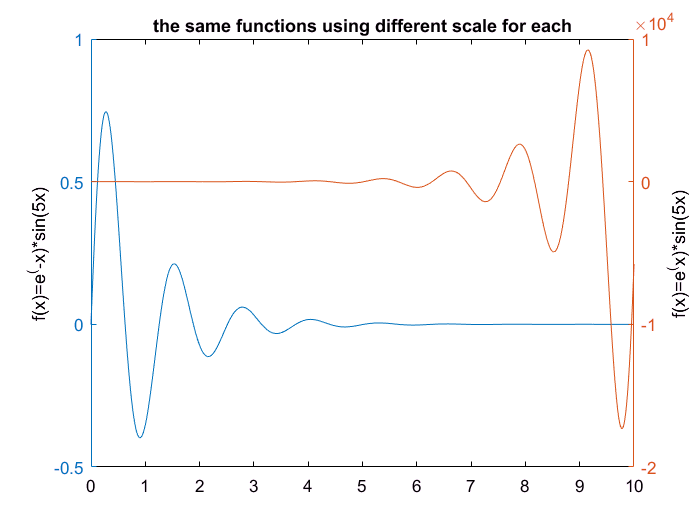

 %plotting them in the same figure but with two different axes and scale.
figure(2);[h,a,b]=plotyy(x,f,x,g);title('the same functions using different scale for each');   
ylabel(h(1),'f(x)=e^(-x)*sin(5x)');
ylabel(h(2),'f(x)=e^(x)*sin(5x)');

%%
%this section checks whether or not a matrix is magic.
%this code is run three times and each time the output is shown.
%first run with magic(4) as input matrix.
clear
a=input('\ninput matrix to determine whether is magic or not:');

%checking whether or not the matrix is square
asize=size(a);
if mod(sum(asize),2)~=0 fprintf('\ninput matrix is not a square matrix\n');  
else 
    diagsum=sum(diag(a));%calculating sum of each row and column and the diagnol.
    columnsum=sum(a);
    rowsum=sum(a');
      %checking whether or not the mentioned sums are equal or not
    if diagsum==columnsum & diagsum==rowsum ,fprintf('YES\n');
    else fprintf('NO\n'); end
end

YES


%second run with an arbitrary matrix:[1 2;3 4]
clear
a=input('\ninput matrix to determine whether is magic or not:');
asize=size(a);
if mod(sum(asize),2)~=0 fprintf('\ninput matrix is not a square matrix\n'); 
else 
    diagsum=sum(diag(a));
    columnsum=sum(a);
    rowsum=sum(a');
    if diagsum==columnsum & diagsum==rowsum ,fprintf('YES\n');
    else fprintf('NO\n'); end
end

NO


%third run with a nonsquare matrix:[1,2]
clear
a=input('\ninput matrix to determine whether is magic or not:');
asize=size(a);
if mod(sum(asize),2)~=0 fprintf('\ninput matrix is not a square matrix\n'); 
else 
    diagsum=sum(diag(a));
    columnsum=sum(a);
    rowsum=sum(a');
    if diagsum==columnsum & diagsum==rowsum ,fprintf('YES\n');
    else fprintf('NO\n'); end
end


input matrix is not a square matrix


%%
%this is the answer to the system AX=B
clear
A=[2 9 3 0 6 2 9 4 5 7;4 9 7 5 3 2 8 0 6 4;
    0 0 6 8 1 6 8 5 4 0;9 7 5 6 4 2 2 4 8 2;
    1 2 6 1 4 8 5 6 7 1;1 4 6 3 1 9 0 6 9 2;
    3 5 1 4 5 7 4 6 5 4;1 9 1 9 2 3 3 0 3 5;
    4 4 9 1 3 5 1 0 1 4;3 9 1 8 5 1 1 3 6 8];
B=[217;279;227;236;156;285;225;262;164;168];
X=A\B

X =    16.0927
   21.3025
    0.5651
    1.9204
  -41.4731
   17.3017
   11.6029
   14.9978
   -5.4758
    9.7991


%We could also calculate X using inv(A)*B
%%
fprintf('The inverse is:\n');disp(inv(A))

The inverse is:
   -0.1067    0.2221    0.0032   -0.0199   -0.2713    0.0470    0.3100   -0.2306    0.0133   -0.0081
    0.2645   -0.3722   -0.0293    0.2189    0.1340    0.0057   -0.3266    0.4102    0.0214   -0.2220
    0.1165   -0.1922    0.0554    0.0939    0.1043   -0.0097   -0.2698    0.1165    0.0891   -0.0224
   -0.0494   -0.0370    0.0525    0.0198    0.0424   -0.0517   -0.0386    0.0592   -0.0022    0.0478
   -0.0430   -0.1652   -0.1018    0.0658    0.4966   -0.2777   -0.1882    0.1880    0.0196    0.0780
   -0.1397    0.1737   -0.0556   -0.1170   -0.0583    0.0334    0.2600   -0.0593    0.0118   -0.0352
   -0.0312    0.1884    0.0375   -0.0809   -0.1150    0.0018    0.1628   -0.1285   -0.0432   -0.0123
    0.3403   -0.4793    0.1377    0.2356   -0.0381    0.0676   -0.2915    0.2180    0.0407   -0.1401
   -0.2185    0.3654   -0.0764   -0.1540   -0.0003    0.0493    0.1777   -0.2666   -0.1165    0.1708
   -0.1381    0.3601    0.0439   -0.2595   -0.3787    0.1357    0.3644   -0

fprintf('sum of each row is:\n');z=sum(A');disp(z');

sum of each row is:
    47
    48
    38
    49
    41
    41
    44
    36
    32
    45


fprintf('average of each column is:');format bank;disp(mean(A))

average of each column is:          2.80          5.80          4.50          4.50          3.40          4.50          4.10          3.40          5.40          3.70


fprintf('The variance of the diagnol of A is:');format;disp(var(diag(A)))

The variance of the diagnol of A is:   10.5444



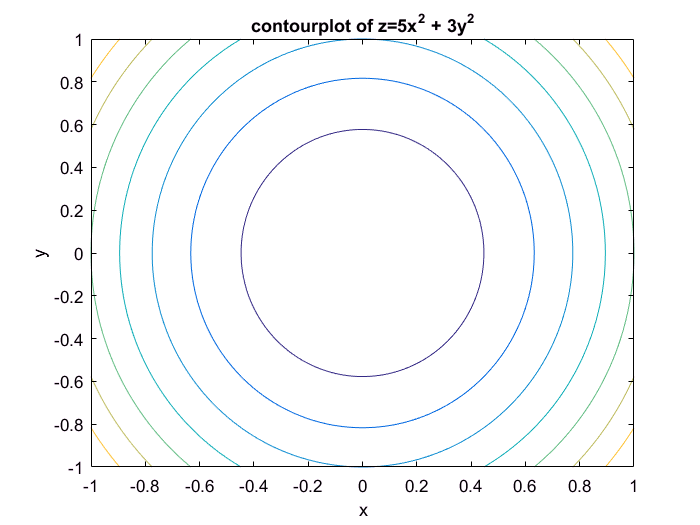

%%
clear
[x,y]=meshgrid(-1:.01:1);    %initilizing x and y and then introducing z
z=5*x.^2+3*y.^2;
 %opening a figure for each plot and adding titles and labels.
figure(1);contour(x,y,z);title('contourplot of z=5x^2 + 3y^2');xlabel('x');ylabel('y');

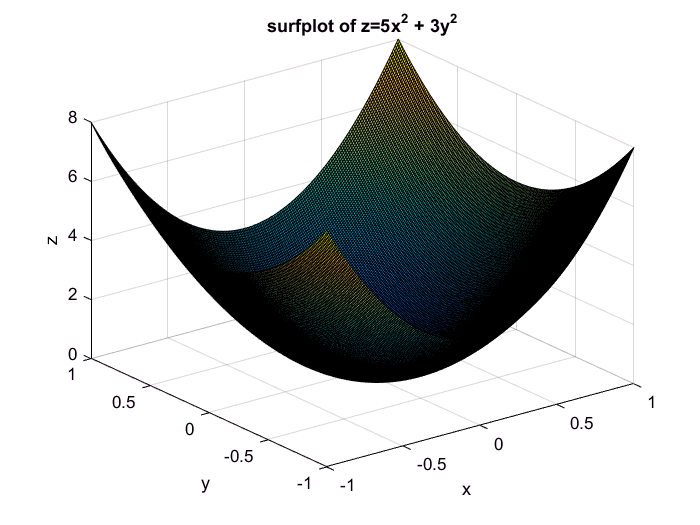

figure(2);surf(x,y,z);title('surfplot of z=5x^2 + 3y^2');xlabel('x');ylabel('y');zlabel('z');

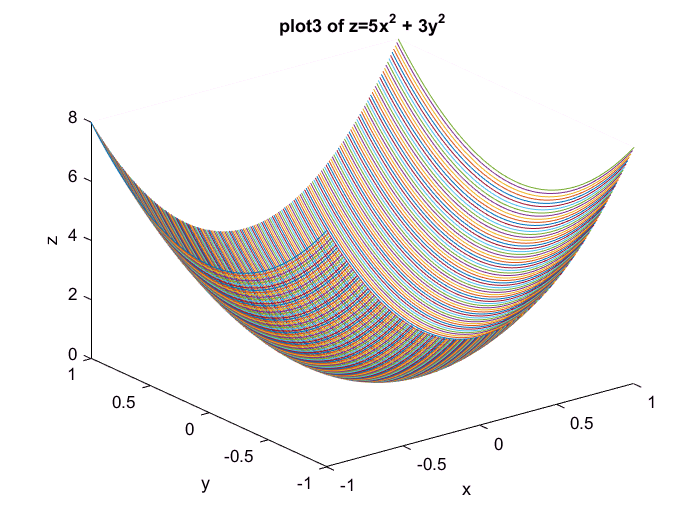

figure(3);plot3(x,y,z);title('plot3 of z=5x^2 + 3y^2');xlabel('x');ylabel('y');zlabel('z');


%%
clear
 %generating a random matrix of dimentions 10 by 10 with only integers 0 to 10
A=floor(11*rand(10,10));                
t=input('to display the matrix,enter 1.otherwise enter 0:');
if t==1 ,disp(A);end

     0    10     0     8     6     9     8     9     5     6
     8    10     0     3     9     6     6     6     4     5
     9     4     4     6     1    10     3     5     0     1
     1     2    10     3     6     4     1     6     9     5
     2     3     2     4     1     6     8     4     5     0
     1     8     9     1     7     9     2     6     4     7
    10     7     2     5     7     4     6     6     1     3
     0     8     3     2     0     0     9     8     7     9
     8     7    10     2     4     5     9     1     2     3
     8     5     8     8     5     2     8     0     1     6



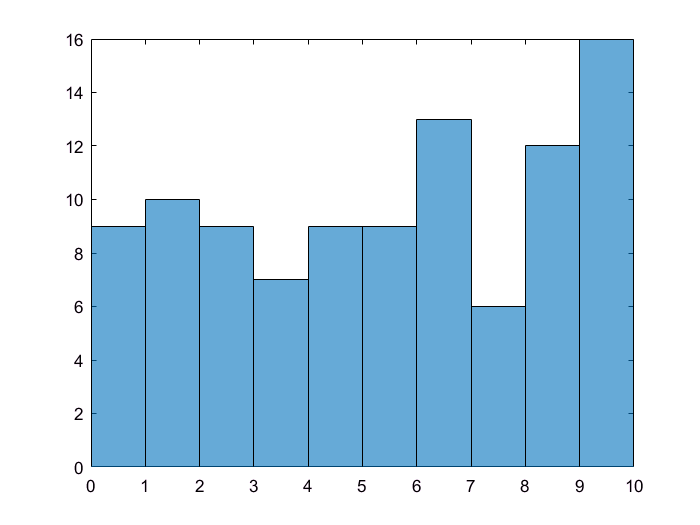

%the function histogram takes as input, in this case particularly, first the data set matrix and second the number of rectangles
histogram(A,10);